## MAPS2001 project draft

# Analysis of Atmospheric Stable Water Isotopes and Related Movements of Air

## Abstract

## Introduction

## Computational Methodology

**        1) Simple Initial Analysis of Data (Valentia GNIP Station)**

First, to understand the format and to visualize the data, Valentia Observatory (Ireland) was randomly chosen. Simple analysis has been conducted.

IAEA WISER data for Valentia GNIP station was downloaded and imported to MATLAB.

clear all
clf
v = 'valentia.xlsx';

Readtable function was used to easily extract data from the Excel file.

s = readtable (v); % reading data from the specific Data File

IAEA WISER GNIP date were found to be not in a chronological order. To easily manipulate the data in general, the sorting function had to be invented and used.

%%% sort the data by date: %%%
allDates=s.Date(:); % gives all dates in one cell
A = datetime(allDates,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDates,originalIndex]=sort(A); %sorts A array (708x1 - includes only dates) into ascending order.
                                  %originalIndex gives the original index or s table

sortedS=s(originalIndex,:); %print s table with originalIndex, which gives data in ascending date

The simple trends such as the variance of abundances of deuterium, tritium and oxygen with respect to time were plotted (scatter plot).

Saving measurements for deuterium, tritium and oxygen as variables:

% convenient labelling of variables
H2 = sortedS. H2;
H3 = sortedS.H3;
O18 = sortedS.O18;

Deuterium variance with respect to time:

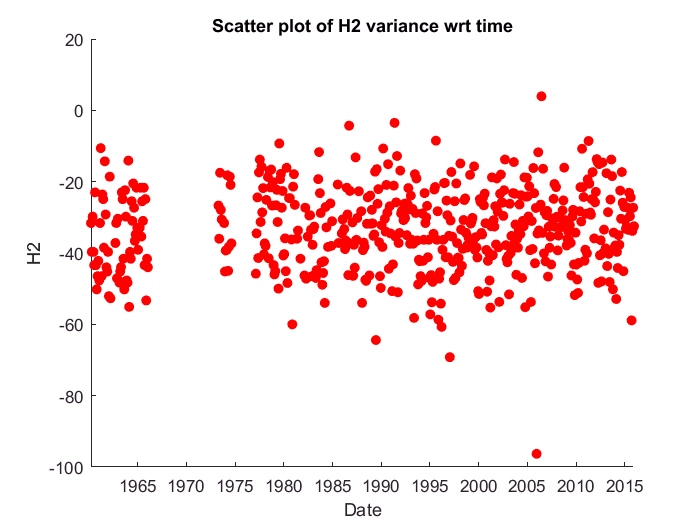

figure (1)
scatter (sortDates, H2, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H2 variance wrt time')

Tritium variance with respect to time:

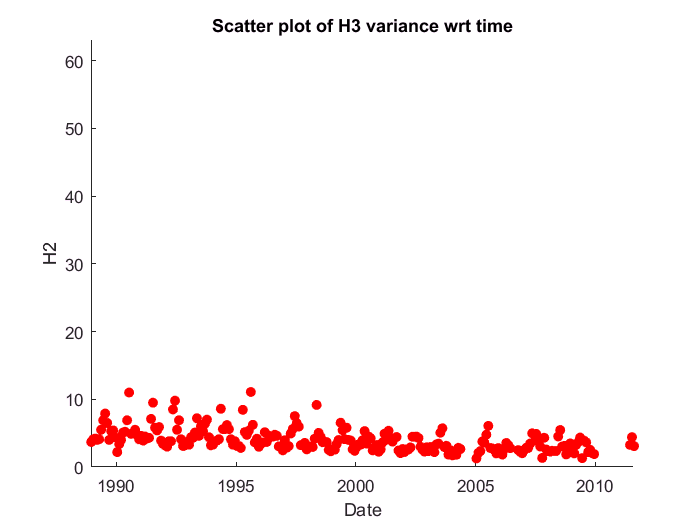

figure (2)
scatter (sortDates, H3, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('H2');
title ('Scatter plot of H3 variance wrt time')

Oxygen variance with respect to time:

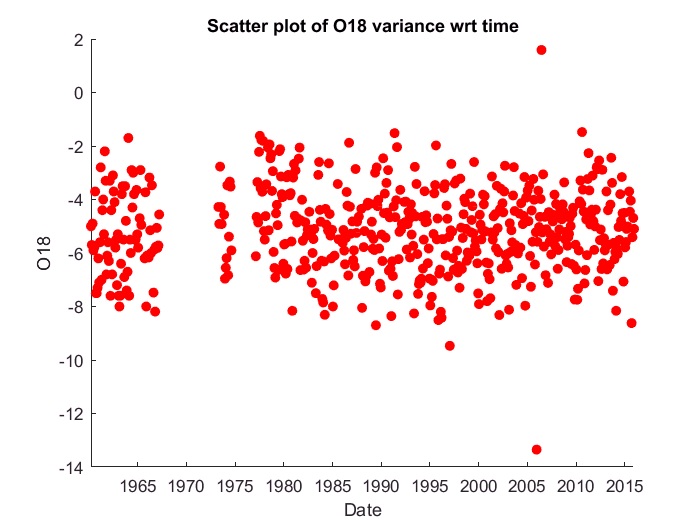

figure (3)
scatter (sortDates, O18, 'ro', 'filled');
datetick('x','yyyy','keeplimits');
xlabel ('Date');
ylabel ('O18');
title ('Scatter plot of O18 variance wrt time')

**    2. Comparison of isotope precipitation rate to average annual temperature word-wide and visualising possible correlation**

**        3. Reproduction of a Graph from the Main Reference **$\delta D$** vs. precipitation rate**

To reproduce some of the analysis in tropics according to the main reference:

*G. Torri, D. Ma, Z. Kuang Stable water isotopes and large-scale vertical motions in the tropics, Journal of Geophysical Research: Atmospheres Volume 122, Issue 7, pages 3703-3717, 2017, *

the plot from page 3714: $\delta D$ vs. precipitation rate was replotted in order to produce a piece of code with same/similar results. The data from IAEA WISED database for West and East Pacific was donwloaded accordingly:

**West:** (15° N - 15° S, 120° E - 180° E): Darwin, Jayapura, Madang, Tarawa, Truk, Yap

**East**: (15° N - 15° S, 180° E - 240° E): Apia, Canton Island, Christmas Island

% reproduced graph from the main reference
% precipitation rate for Eastern and Western Pacific

clear all
clf
% WEST
wt1 = 'WDarwin.xlsx'; % Darwin
wt2 = 'WJayapura.xlsx'; % Jayapura
wt3 = 'WMadang.xlsx'; % Madang
wt4 = 'WTarawa.xlsx'; % Tarawa
wt5 = 'WTruk.xlsx'; % Truk
wt6 = 'WYap.xlsx'; % Yap

% EAST
et1 = 'EApia.xlsx'; % Apia
et2 = 'ECanton_Island.xlsx'; % Canton Island
et3 = 'EChristmas_Island.xlsx'; % Christmas Island

Using readtable function:

% reading data from the specific Data File

% WEST
w1 = readtable (wt1);

w2 = readtable (wt2);

w3 = readtable (wt3);

w4 = readtable (wt4);

w5 = readtable (wt5);

w6 = readtable (wt6);


% EAST
e1 = readtable (et1);

e2 = readtable (et2);

e3 = readtable (et3);

**MANTAS LOOP EXPLANATION INSTEAD OF THIS**

% WEST sort the data by date:
% w1 Darwin
allDatesw1=w1.Date(:); % gives all dates in one cell
Aw1 = datetime(allDatesw1,'Format','yyyy-MM-dd'); % formats 'allDates' cell to an array datetime values

[sortDatesw1,originalIndex]=sort(Aw1); %sorts A array (708x1 - includes only dates) into ascending order.
                                  %originalIndex gives the original index or s table

sortedw1=w1(originalIndex,:); %print s table with originalIndex, which gives data in ascending date

% w2 Jayapura
allDatesw2=w2.Date(:);
Aw2 = datetime(allDatesw2,'Format','yyyy-MM-dd'); 
[sortDatesw2,originalIndex]=sort(Aw2);

sortedw2=w2(originalIndex,:);

% w3 Madang
allDatesw3=w3.Date(:);
Aw3 = datetime(allDatesw3,'Format','yyyy-MM-dd'); 
[sortDatesw3,originalIndex]=sort(Aw3);

sortedw3=w3(originalIndex,:);

% w4 Tarawa
allDatesw4=w4.Date(:);
Aw4 = datetime(allDatesw4,'Format','yyyy-MM-dd'); 
[sortDatesw4,originalIndex]=sort(Aw4);

sortedw4=w4(originalIndex,:);

% w5 Truk
allDatesw5=w5.Date(:);
Aw5 = datetime(allDatesw5,'Format','yyyy-MM-dd'); 
[sortDatesw5,originalIndex]=sort(Aw5);

sortedw5=w5(originalIndex,:);

% w6 Yap
allDatesw6=w6.Date(:);
Aw6 = datetime(allDatesw6,'Format','yyyy-MM-dd'); 
[sortDatesw6,originalIndex]=sort(Aw6);

sortedw6=w6(originalIndex,:);

% EAST sort the data by date:
% e1 Apia
allDatese1=e1.Date(:);
Ae1 = datetime(allDatese1,'Format','yyyy-MM-dd'); 
[sortDatese1,originalIndex]=sort(Ae1);

sortede1=e1(originalIndex,:);

% e2 Canton Island
allDatese2=e2.Date(:);
Ae2 = datetime(allDatese2,'Format','yyyy-MM-dd'); 
[sortDatese2,originalIndex]=sort(Ae2);

sortede2=e2(originalIndex,:);

% e3 Christmas Island
allDatese3=e3.Date(:);
Ae3 = datetime(allDatese3,'Format','yyyy-MM-dd'); 
[sortDatese3,originalIndex]=sort(Ae3);

sortede3=e3(originalIndex,:);

**MORE explanation**

The abundance of deuterium is measured with the following formula:


$$\delta D=\left(\frac{R_{\mathrm{sample}} }{R_{\mathrm{VSMOW}} }-1\right)\cdot 1000\text{ }‰$$


where:

$R_{\mathrm{sample}}$ is the ratio of deuterium to the common, stable isotope of hydrogen in the samples considered,

 $R_{\mathrm{VSMOW}}$ is the same ratio but for a reference sample with the isotopic composition of the Vienna standard mean ocean water.


$$R_{\text{VSMOW}} =155\ldotp 76\pm 0\ldotp 1ppm$$
 

% Delta D versus precipitation rate per day
Rvsmow = 155.76 

Rvsmow = 155.7600

**MANTAS' LOOP instead of this:**

% w1
deltaDw1 = ((sortedw1.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipw1 = [sortedw1.Precipitation, deltaDw1];
% delete NaN rows
graphdataw1 = rmmissing(deltaDprecipw1)

graphdataw1 =    1.0e+03 *

    0.3110   -1.3698
    0.3300   -1.2979
    0.2280   -1.1284
    0.1250   -1.2472
    0.0460   -0.9441
    0.2290   -1.0083
    0.3190   -1.0758
    0.1170   -1.0398
    0.3510   -1.0161
    0.1260   -1.0443



% w2
deltaDw2 = ((sortedw2.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipw2 = [sortedw2.Precipitation, deltaDw2];
% delete NaN rows
graphdataw2 = rmmissing(deltaDprecipw2)

graphdataw2 =    1.0e+03 *

    0.2510   -1.2709
    0.4660   -1.2433
    0.2170   -1.2902
    0.3240   -1.4058
    0.2620   -1.2587
    0.2110   -1.3621
    0.1260   -1.2786
    0.1170   -1.2549
    0.1340   -1.3537
    0.1620   -1.1278



% w3
deltaDw3 = ((sortedw3.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipw3 = [sortedw3.Precipitation, deltaDw3];
% delete NaN rows
graphdataw3 = rmmissing(deltaDprecipw3)

graphdataw3 =    1.0e+03 *

    0.2520   -1.2876
    0.0310   -1.1656
    0.3620   -1.2433
    0.2600   -1.2921
    0.4330   -1.3980
    0.3570   -1.3409
    0.3640   -1.4417
    0.4020   -1.4680
    0.3010   -1.4282
    0.2980   -1.1624



% w4
deltaDw4 = ((sortedw4.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipw4 = [sortedw4.Precipitation, deltaDw4];
% delete NaN rows
graphdataw4 = rmmissing(deltaDprecipw4)

graphdataw4 =    1.0e+03 *

    0.2710   -1.1753
    0.3070   -1.2010
    0.0190   -1.1124
    0.3080   -1.2857
    0.4070   -1.3043
    0.5030   -1.2696
    0.1620   -1.1188
    0.1150   -1.1990
    0.0990   -1.1374
    0.1790   -1.2131



% w5
deltaDw5 = ((sortedw5.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipw5 = [sortedw5.Precipitation, deltaDw5];
% delete NaN rows
graphdataw5 = rmmissing(deltaDprecipw5)

graphdataw5 =    1.0e+03 *

    0.3530   -1.1573
    0.5210   -1.1207
    0.2540   -1.1984
    0.3610   -1.2228
    0.4000   -1.2427
    0.1970   -1.1900
    0.3140   -1.2388
    0.1760   -1.2164
    0.6230   -1.1412
    0.0370   -1.0128



% w6
deltaDw6 = ((sortedw6.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipw6 = [sortedw6.Precipitation, deltaDw6];
% delete NaN rows
graphdataw6 = rmmissing(deltaDprecipw6)

graphdataw6 =    1.0e+03 *

    0.1460   -1.2555
    0.3620   -1.2594
    0.2710   -1.1695
    0.2850   -1.3229
    0.0910   -1.2696
    0.2120   -1.1766
    0.1040   -0.9917
    0.0320   -0.9480
    0.0530   -0.9653
    0.0770   -1.3017



% e1
deltaDe1 = ((sortede1.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipe1 = [sortede1.Precipitation, deltaDe1];
% delete NaN rows
graphdatae1 = rmmissing(deltaDprecipe1)

graphdatae1 =    1.0e+03 *

    0.4350   -1.1091
    0.3570   -1.1079
    0.4710   -1.1952
    0.2430   -1.0957
    0.1730   -1.1079
    0.5110   -1.1079
    0.2650   -1.1599
    0.0670   -1.0321
    0.1220   -1.0681
    0.0590   -0.9839



% e2
deltaDe2 = ((sortede2.H2./Rvsmow)-1).*1000; % delta D according to the formula
deltaDprecipe2 = [sortede2.Precipitation, deltaDe2];
% delete NaN rows
graphdatae2 = rmmissing(deltaDprecipe2)

graphdatae2 =    1.0e+03 *

    0.0030   -0.9480
    0.0040   -1.0122
    0.0200   -1.0122
    0.1430   -1.1316
    0.0620   -1.0122
    0.0130   -0.9839
    0.0690   -1.0083
    0.0640   -1.0199
    0.0060   -0.9197
    0.0040   -0.9037



% e3
deltaDe3 = ((sortede3.H2./Rvsmow)-1).*1000 % delta D according to the formula

deltaDe3 =    1.0e+03 *

       NaN
       NaN
   -1.1040
   -1.1355
   -1.0321
   -1.0282
   -1.0719
       NaN
   -0.9961
   -1.0282


deltaDprecipe3 = [sortede3.Precipitation, deltaDe3];
% delete NaN rows
graphdatae3 = rmmissing(deltaDprecipe3)

graphdatae3 =    1.0e+03 *

    0.0770   -1.1040
    0.1920   -1.1355
    0.1350   -1.0321
    0.0500   -1.0282
    0.1090   -1.0719
    0.0110   -0.9961
    0.0060   -1.0282
    0.0090   -1.0443
    0.0040   -0.9839
    0.0120   -1.0199


**JAMES**

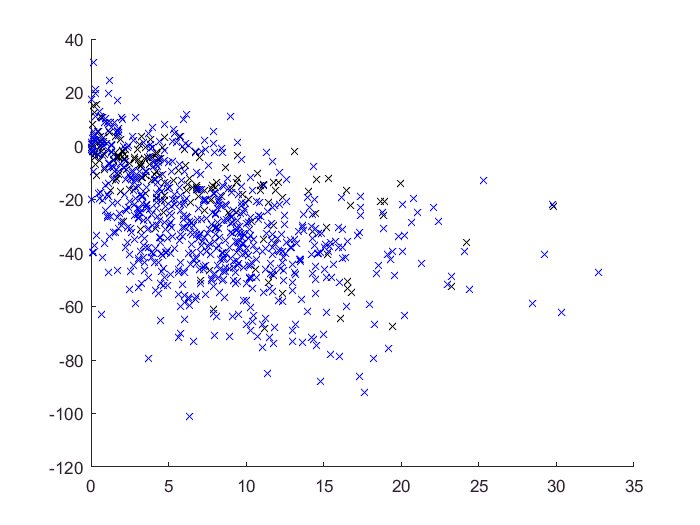

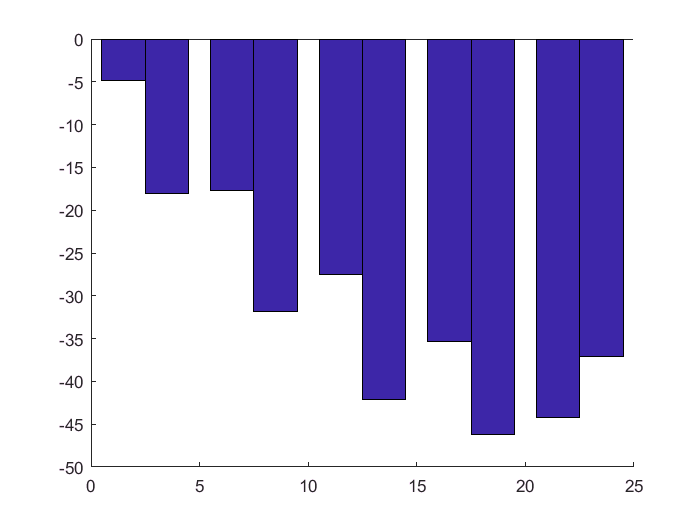

w1.Comment=[];
w2.Comment=[];
w3.Comment=[];
w4.Comment=[];
w5.Comment=[];
w6.Comment=[];

clf
wFull=[w1;w2;w3;w4;w5;w6];
%Concatenating the data frpm the varioys western stations
eFull=[e1;e2;e3];
%doing the same for the eastern stations
figureNumScatter=10;
figureNumBins=20;
%setting figure numbers for the two graphs I want to plot (unbinned ppt per day versus deltaH2
% and binned data)

%I make a loop so I can plot the graphs twice using the same loop, switching between east and west each time
for j=[1,2]
 if j==1
     %for the Eastern Loop
     s=eFull;
     pointColour='xblack';
     
 else
     %Western loop
     s=wFull;
     pointColour='xb';
     
 end
%retrieving relevangt data
d=datenum(s.Date,'yyyy-mm-dd');
H3=s.H3;
H2=s.H2;
O18=s.O18;
%finding how many days there were per month
numdays=(datenum(s.EndOfPeriod, 'yyyy-mm-dd')- datenum(s.BeginOfPeriod,'yyyy-mm-dd')+1);
%precipitation per day
pppday=s.Precipitation./numdays;
%see a scatter plot of the data
figure(figureNumScatter)
hold on
plot(pppday,H2,pointColour)
hold off
xlabel('PPT per day')
ylabel('deltaH2')
%Deciding our bin sizes
Edges=[0,5,10,15,20,25];
%Finding out which deltaH2s fall in each ppt/day
[pppdaybin,Edge]= discretize(pppday,Edges);

%pppdaybin= which 'bin' each pppday in the array falls in
%I want to get the array of deltaH2 for each bin
for i=1:(length(Edge)-1)
 %I use a structure as it is easier to use with loops
 %we makr the struct separated by bin
H2binned(i).H2=H2(pppdaybin == i);
end

for i=1:(length(Edge)-1)
    %I then find the mean of these binned deltaH2 (along with the standard deviations
    H2binned(i).mean = nanmean(H2binned(i).H2);
    H2binned(i).error = nanstd(H2binned(i).H2);
end

for i=1:(length(Edge)-1)
    %we switch these back to an array, so we can more conveniently use this data (ouside of loops)
    H2binnedmeans(i)=H2binned(i).mean;
    H2binnedmeanserror(i)=H2binned(i).error;
end
%I want to now plot the mean H2 binned, versus the midvalue of each bin:
%To get an array of the midvalues,I create an array of the start and end points of each bin, and then mean them

MidEdge(1,:)=Edge(1:(length(Edge)-1));
MidEdge(2,:)=Edge(2:length(Edge));
MidEdge=mean(MidEdge);
%We now plot the graph, and use 'bar' function to plot as bars (as in the original paper)
if j==1
    %we shift the bars for the first loop (East) to the positive
    MidEdgeShift=-1;
else
    %and the bars for the second loop (West) to the negative
    MidEdgeShift=1;
end
%we now plot our bar graph
figure(figureNumBins)
%including earlier calculated shift
pointPosn=MidEdge+MidEdgeShift;
hold on
%create a bar object so we can edit its properties
b=bar(pointPosn,H2binnedmeans);
%and reduce its width to allow us to see both bars at once
b.BarWidth=0.4;
%TO DO: include error bars, make it look pretty, do for other isotoipes/geographic regions
%Critical discussion of results: +++++++different to the graph in the paper- possible reasons:
%-different date range
%-different methodology? Although would imagine gthat this should still porduce the rsame results?

hold off

end

## Critical Discussion of Results

**        1) Simple Initial Analysis of Data (Valentia GNIP Station)**

## Conclusions and Future Work